R = 1

R = 1

Km = 1/R

Km = 1

Khach = 48

Khach = 48

Kcourant = 0.10416

Kcourant = 0.1042

Kf = 1.79

Kf = 1.7900

K = Km*Khach*Kcourant*Kf

K = 8.9494

ft = 400

ft = 400


fm=80

fm = 80

tau_m = 1/(2*pi*fm)

tau_m = 0.0020


ff=2000

ff = 2000

tau_f = 1/(2*pi*ff)

tau_f = 7.9577e-05


tau_i = K/(2*pi*ft) 

tau_i = 0.0036

fi = 1/(2*pi*tau_i)

fi = 44.6956

tau_c = tau_m

tau_c = 0.0020


Gm=tf([Km], [tau_m 1])

Gm =
 
        1
  --------------
  0.001989 s + 1
 
Continuous-time transfer function.



F=tf([Kf], [tau_f 1])

F =
 
       1.79
  ---------------
  7.958e-05 s + 1
 
Continuous-time transfer function.



C=tf([tau_c 1],[tau_i 0])

C =
 
  0.001989 s + 1
  --------------
    0.003561 s
 
Continuous-time transfer function.




G=K*Gm*F*C

G =
 
              0.03187 s + 16.02
  ------------------------------------------
  5.637e-10 s^3 + 7.367e-06 s^2 + 0.003561 s
 
Continuous-time transfer function.



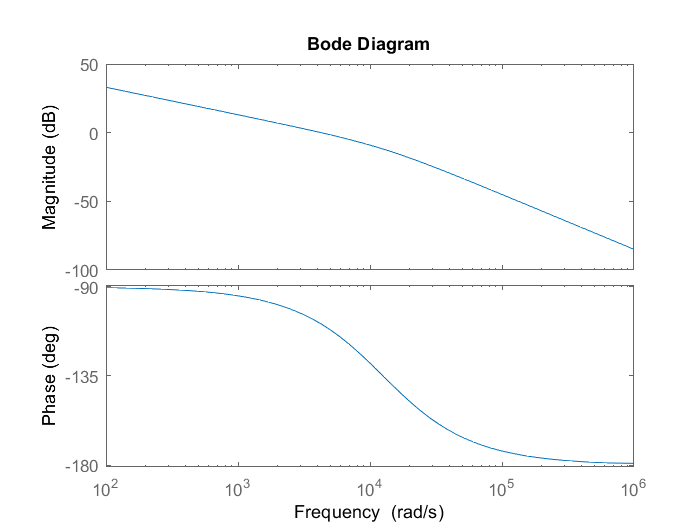

bode(G)

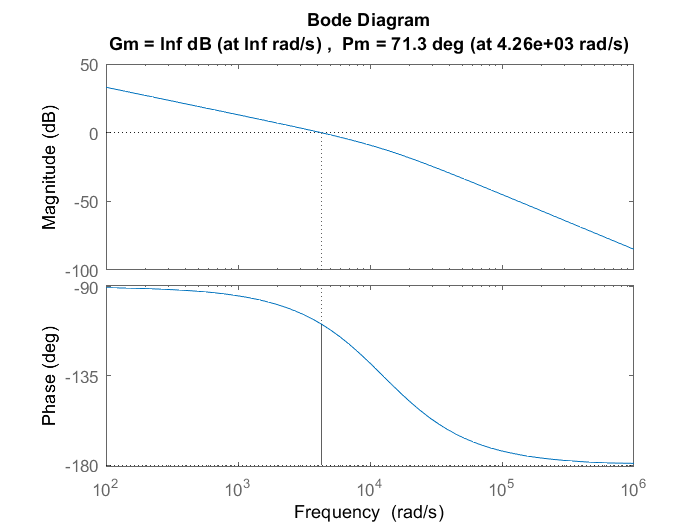

margin(G)

On n a pas la bonne freq de transfert, il y a un pb qq part